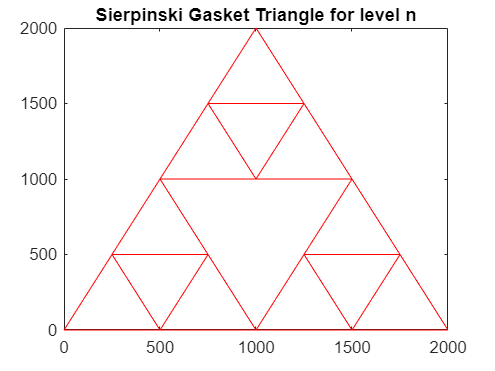

% 'm' (line 8) is the outter level SGT and 'n' (line 7) is the inner level
% i (line 9) is the interval of integration for the adjacency_matrix
% Input: m,n,i are non-zero positive integers; i is the interval; m < n
% Output: "U_t" the integrated matrix for the interval of i and graph
% equation (1) of "Opinion Dynamics on Graphon: the piecewise constant
% case"

l = []; %an arbitary matrix used to store the nodes in draw_n and draw_m functions
n = 2; %inner level
m = 1; % outter level
left_node = [0 0]; %starting cordinates of left node
top_node = [1000 2000]; %starting cordinates of top node
right_node = [2000 0]; %starting cordinates of right node
i = 100; % number of intervals used to integrate the Opinion Dynamic Equation

nodes_n = draw_n(n+1,left_node, top_node,right_node,l); %drawing SGT for level n matrix and finding its nodes
hold off


nodes_n = unique(nodes_n,'rows','stable') %removing the cordinates of the repeated nodes in level n

nodes_n =            0           0
         250         500
         500           0
         500        1000
         750         500
        1000           0
         750        1500
        1000        1000
        1000        2000
        1250        1500



vertices_triangles_m = draw(m+1,left_node, top_node,right_node,l) %drawing SGT for level m matrix and finding its nodes(vertices)

vertices_triangles_m =            0        1000        1000           0
         500        1500        2000        1000
        1000        2000        1000           0


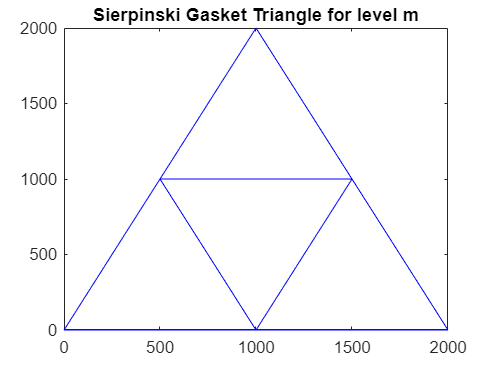

hold off


adjacency_matrix = adjacency(nodes_n,vertices_triangles_m) %function creates the adjacency matrix for the outer level m and inner level n

adjacency_matrix =      0     1     1     1     1     1     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     1     1     1     1     0     0     0     0
     1     1     1     1     0     1     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     0     0     0     0     0     1     1     1     1     1
     0     0     0     1     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     1     0     0     1     0     1     1     1     0     0     0     0
     0     0     0     1     0     0     1     1     0     1     1     0     0     0     0
     0     0     0     1     0     0     1     1     1     0     1     0     0     0     0



U_t_0 = sum(adjacency_matrix == 1) % number of neighbouring nodes for each node

U_t_0 =      5     5     5    10     5    10     5     5     5     5    10     5     5     5     5


draw =     5.0000    4.3333    4.7778    4.4815    4.6790    4.5473    4.6351    4.5766    4.6156    4.5896    4.6069    4.5954    4.6031    4.5979    4.6014    4.5991    4.6006    4.5996    4.6003    4.5998    4.6001    4.5999    4.6001    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000
    5.0000    4.3333    4.7778    4.4815    4.6790    4.5473    4.6351    4.5766    4.6156    4.5896    4.6069    4.5954    4.6031    4.5979    4.6014    4.5991    4.6006    4.5996    4.6003    4.5998    4.6001    4.5999    4.6001    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000    4.6000  

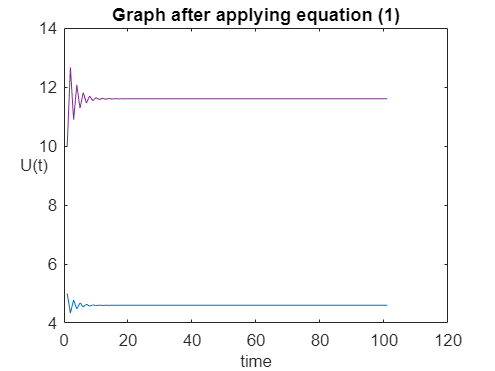


U_t = integrate_U_t(U_t_0, i, adjacency_matrix); % this function is called to plot the graph for the equation 01 in Opinion Dynamic

## Integrate U_t

function U = integrate_U_t(U_t, interval, B_M)
len = length(B_M);
draw = U_t'; % this matrix doesn't have a mathematical use, only used to draw
temp1 = U_t; % this matrix doesn't have a mathematical use, only used to draw

% for loop is used to iterate the equation for each interval
for k = 1 : interval
    temp_t = [];
    for i = 1 : len
        x = 0;
        for j = 1 : len
            x = x + B_M(i,j)*(U_t(j) - U_t(i))/len; % the equation for the integration
        end
        temp_t = [temp_t,x];
    end
    temp1 = temp1 - temp_t;
    draw = [draw temp1'];
    U_t = temp_t;
end
draw
U = U_t;

% plots the graph for the integration
for i = 1 : size(draw,1)
    plot(draw(i,:))       % plot W against t
    xlabel('time','FontSize',10)
    ylabel('U(t)','FontSize',10,'Rotation',0)
    title("Graph after applying equation (1)")
    hold on
end
hold off
ylim("auto")
end

## Adjacency Matrix

function adjacency_matrix = adjacency(nodes, vertices)
len = length(nodes);
M = zeros(len);
for i = 1 : len
    M(i,i) = 0;
    for j = i + 1 : len
        for k = 1 : length(vertices(:,1))
            x = [vertices(k,1) vertices(k,2) vertices(k,1)/2+vertices(k,2)/2];
            y = [vertices(k,4) vertices(k,4) vertices(k,3)];
            %plot(x,y, "r-")
            %hold on
            [in1,on1]=inpolygon(nodes(i,1),nodes(i,2) ,x, y);
            if in1 == 1 || on1 == 1
                [in2,on2]=inpolygon(nodes(j,1),nodes(j,2) ,x, y);
                if in2 == 1 || on2 == 1
                    M(i,j) = 1;
                    M(j,i) = 1;
                end
            end
        end
    end
end
adjacency_matrix = M;
end

## Draw SGT for n

function e = draw_n(n,left_node, top_node,right_node,l)
if n == 1
    x = [left_node(1),top_node(1),right_node(1),left_node(1)];
    y = [left_node(2),top_node(2),right_node(2),left_node(2)];
    plot(x,y,"r-")
    title("Sierpinski Gasket Triangle for level n")
    l = [l;left_node];
    l = [l;top_node];
    l = [l;right_node];
    hold on
else
    left_top_mid = midpoint(left_node,top_node);
    top_right_mid = midpoint(top_node, right_node);
    left_right_mid = midpoint(left_node, right_node);

    l=draw_n(n - 1,left_node,left_top_mid,left_right_mid ,l);
    l=draw_n(n - 1,left_top_mid,top_node,top_right_mid,l);
    l=draw_n(n - 1,left_right_mid, top_right_mid,right_node,l);
end
e = l;
end

## Midpoint

function point = midpoint(point1,point2)
x = (point1(1)+point2(1))/2;
y = (point1(2)+point2(2))/2;
point = [x,y];
end

## Draw SGT for m

function e = draw(n,left_node, top_node,right_node,l)
if n == 1
    x = [left_node(1),top_node(1),right_node(1),left_node(1)];
    y = [left_node(2),top_node(2),right_node(2),left_node(2)];
    m = [left_node(1) right_node(1) top_node(2) right_node(2)];
    plot(x,y,"b-")
    title("Sierpinski Gasket Triangle for level m")
    l = [l;m];
    hold on
else
    left_top_mid = midpoint(left_node,top_node);
    top_right_mid = midpoint(top_node, right_node);
    left_right_mid = midpoint(left_node, right_node);

    l=draw(n - 1,left_node,left_top_mid,left_right_mid ,l);
    l=draw(n - 1,left_top_mid,top_node,top_right_mid,l);
    l=draw(n - 1,left_right_mid, top_right_mid,right_node,l);
end
e = l;
end
